# Heat flow on a dumbbell graph

Solve the heat equation 


$$u_t = \triangle u$$


on a dumbbell graph using the Crank-Nicholson method with time step $h$:


$$u_{k+1} = \left(I - \frac{h}{2}\triangle\right)^{-1}
 \left(I +\frac{h}{2}\triangle\right) u_k$$


## Set up the graph and the initial condition

%nX=32; %increase the resolution compared with the default
%Phi=quantumGraphFromTemplate('dumbbell','nX',nX,'Discretization','Chebyshev');
nX=5; %increase the resolution compared with the default
Phi=quantumGraphFromTemplate('dumbbell','nX',nX);
f0=@(x)(2-cos(x));
f1=1;
f2=@(x)cos(x);
Phi.applyFunctionsToAllEdges({f0,f1,f2});
y=Phi.graph2column;

## Set up the time stepping

dt=0.01;
tPlot=0.5;
tFinal=10;
nSkip=tPlot/dt;
nStep=tFinal/dt;

## Set up places to save data

t=0:tPlot:tFinal;
nSave=length(t);
Y=zeros(length(y),nSave);
totalHeatVector=zeros(size(t));
totalHeatVector(1)=Phi.integral(y);

## Set up the evolution matrices

A=Phi.laplacianMatrix;
B=Phi.weightMatrix;
Aplus=B+dt/2*A;
Aminus=B-dt/2*A;

## Evolve  the solution

keepCount=1;
for k=1:nStep
    y = Aplus*y;
    y = Aminus\y;
    if mod(k,nSkip)==0
        keepCount=keepCount+1;
        Y(:,keepCount)=y;
        totalHeatVector(keepCount)= Phi.integral(y);
    end
end

## Show that the total heat is conserved

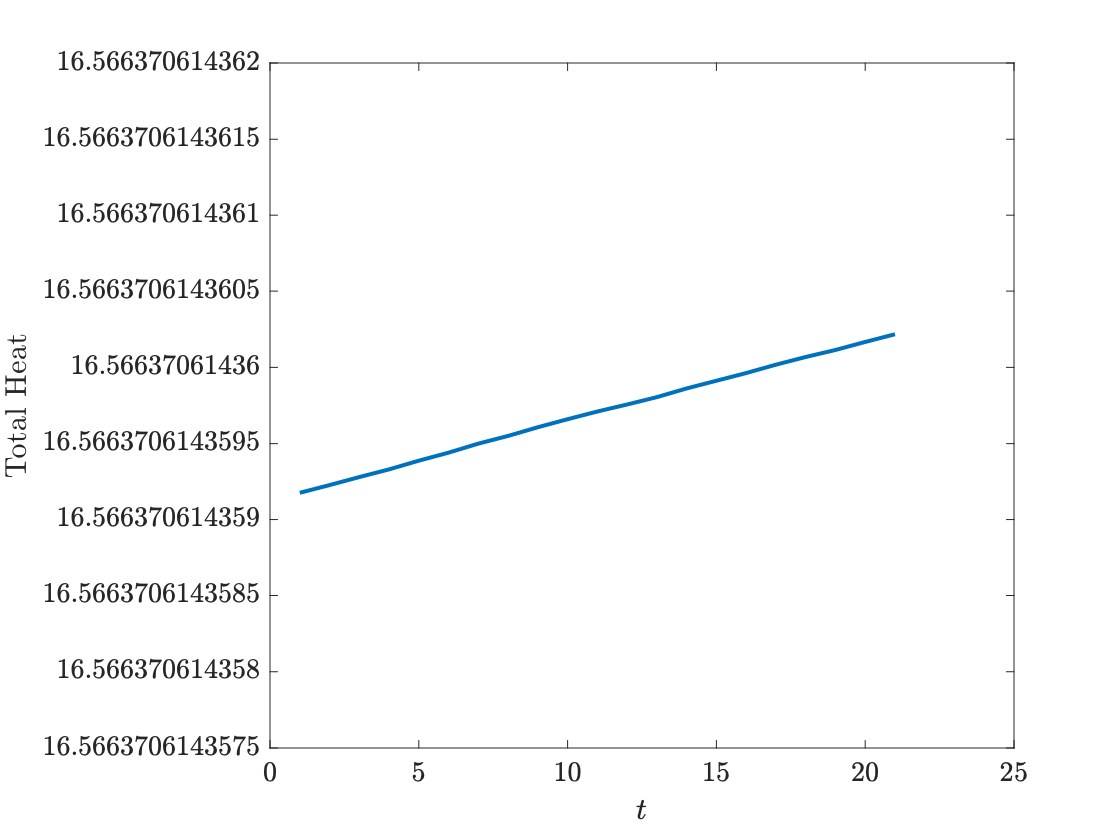

plot(totalHeatVector)
xlabel('$t$')
ylabel('Total Heat')

fprintf('Change in heat is %0.2e',max(totalHeatVector)-min(totalHeatVector))

Change in heat is 1.04e-12

## Animate the solution

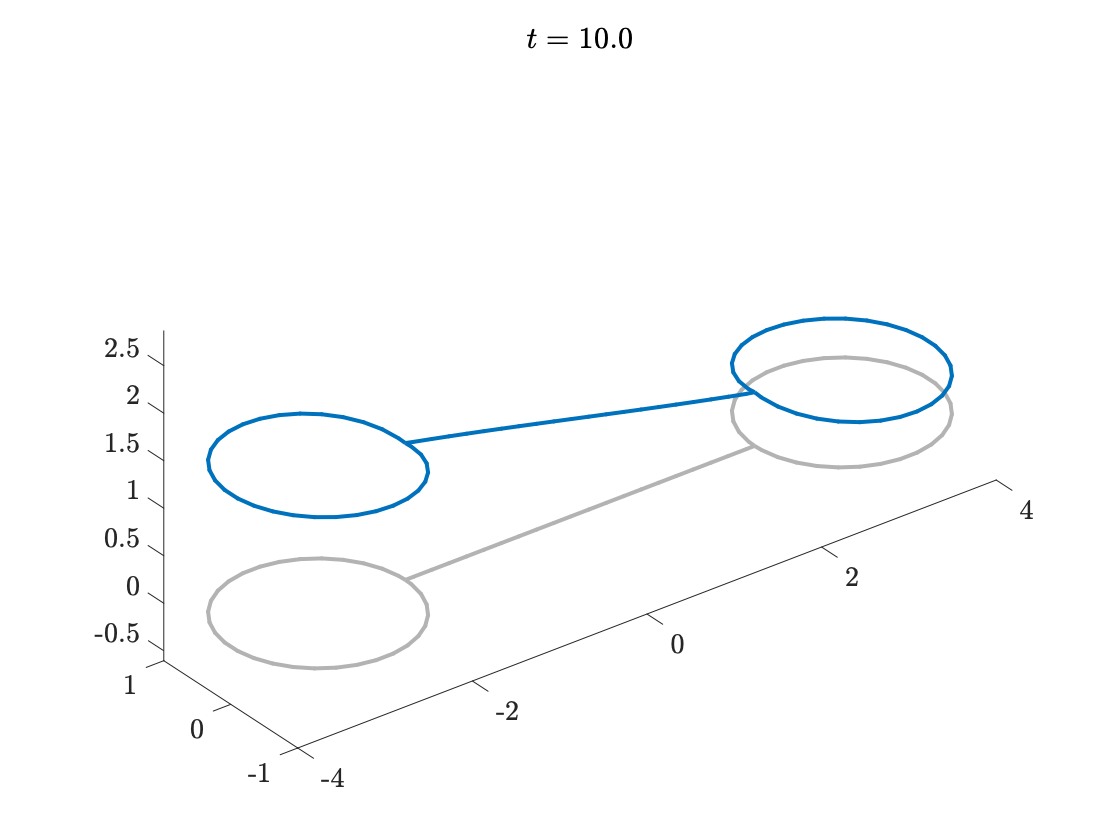

Phi.animatePDESolution(Y,t);